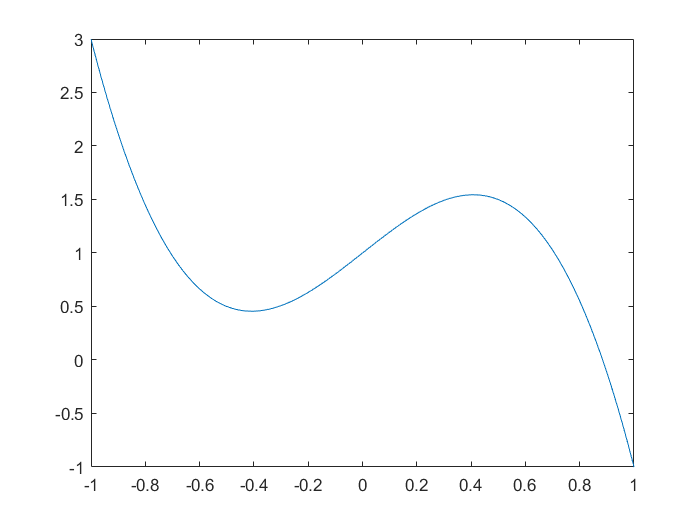

z=linspace(-1,1,101);
c=[-4 0 2 1];
p=polyval(c,z);
plot(z,p)

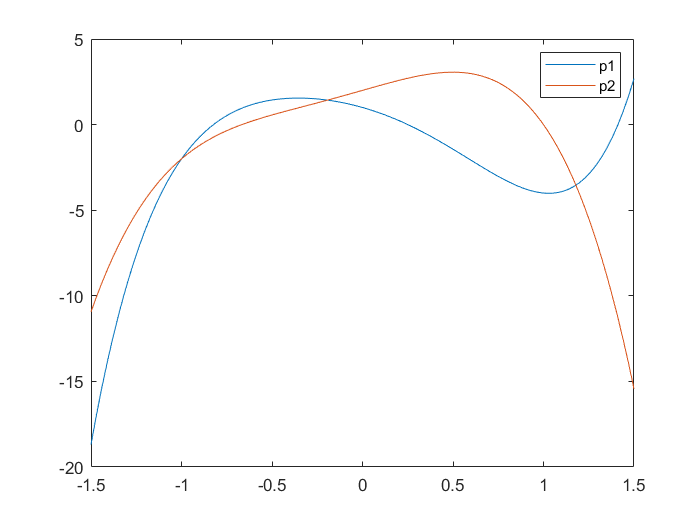

figure()

x=linspace(-3/2,3/2,101);
c1=[2 0 0 -4 -3 1];
p1=polyval(c1,x);
plot(x,p1)
hold on

c2=[-3 -2 0 3 2];
p2=polyval(c2,x);
plot(x,p2)
legend("p1","p2")


figure()
x=0.995:1.e-4:1.005;
c3=[1 -6 15 -20 15 -6 1];
p3=polyval(c3,x);
plot(x,p3)
hold on 

f=@(x) (x-1)^6

f = function_handle with value:
    @(x)(x-1)^6


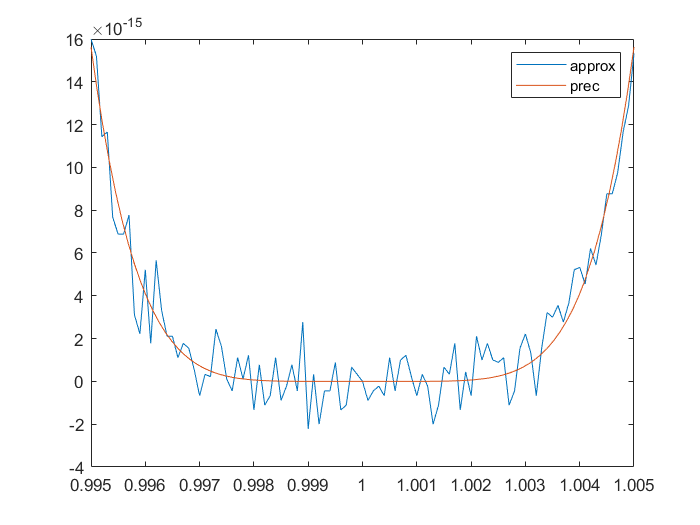

fplot(f,[0.995 1.005])
legend("approx","prec")


figure()
x=0:4;
y=[2 0 -1 -2 1];
plot(x,y,"or")
hold on
c=polyfit(x,y,4)

c =     0.2083   -1.4167    3.2917   -4.0833    2.0000


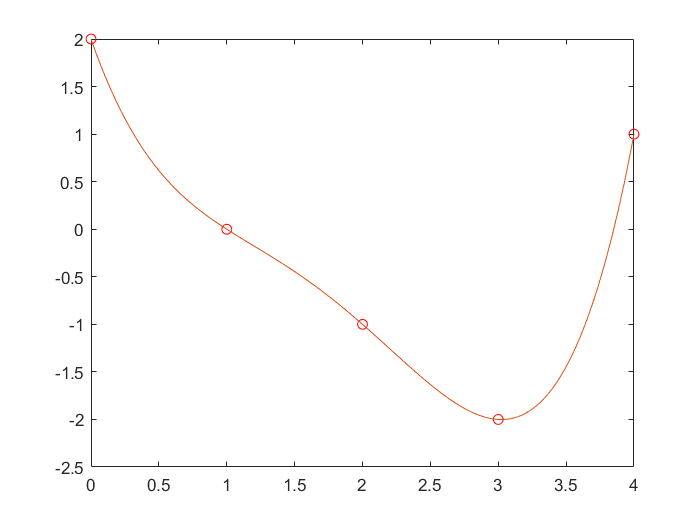

x=0:0.01:4;
y=polyval(c,x);
plot(x,y)

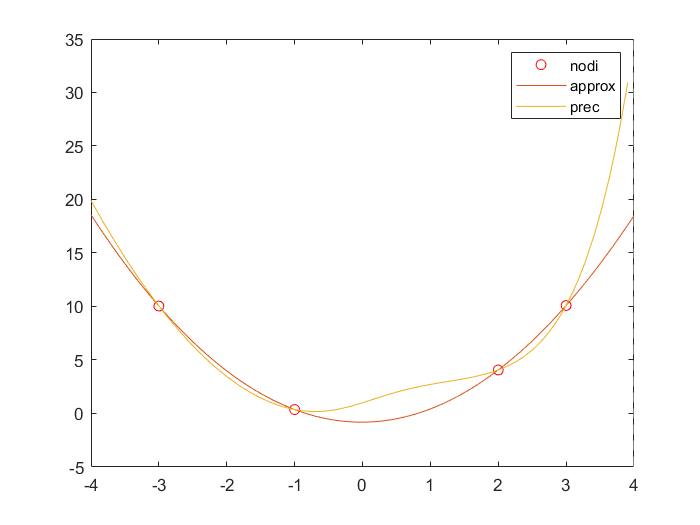


figure()
x=[-3 -1 2 3];
f=@(x) (1-x.^2).*atan(x)+exp(x);
y=f(x);
plot(x,y,"or")
hold on
p=polyfit(x,y,3);
y=polyval(p,-4:0.1:4);
plot(-4:0.1:4,y)
fplot(f,[-4 4])
legend("nodi","approx","prec")